## **Multi RBS analysis**

This script intend to vary the parameters of fractal coding to inspect the effect.

**This script include**

- effect of power 1's coefficient limitation

- effect of fix partittion vs adaptive partition

- effect of multi scale at vs fix scale

- apply to synth 8, 16k and 5 random 8, 16k speech 

**The metrices include**

- diff psnr

- diff spectrum visualization

- diff signal visualization

## **Let start with synthesize signal**

**First experiment is effect of **`coeff limit`** on synth signals**

At finest scale, the rbs-2 is the best but depend on coeff limit.

warning off 
%% parameters
RBS = [8 4 2];
Fs_inout = [1 1]; % Fs in/out ratio

%% read speech-paths
sigDir = 'F:\IFEFSR\SamplesSpeech\synth';
codeDir = 'F:\IFEFSR\SamplesSpeech\code';
filePathsLoc = 'F:\IFEFSR\SamplesSpeech\synth_ids8.txt';
fid = fopen(filePathsLoc,'r');
allFilePaths = textscan(fid, '%s','Delimiter','\n');
allFilePaths = allFilePaths{1};
fclose(fid);

%% for 
for fsIdx = 1:2
    FsShort = 8*fsIdx;
    for idx = 1:1
        %% Read original sig for baseline
        inSigPath = normpath([sigDir '\' num2str(FsShort) ...
            '\' allFilePaths{idx}]);
        sig = rawread(inSigPath);
        
        % plot original sig
        caption = ['Original signal Fs = ' num2str(FsShort) 'k'];
        plotSigVsFreqRes( sig, caption, Fs_inout(2) );
        
        %% read code from dataset
        % no need to use matlab
        F = cell(size(RBS));
        for rbsIdx = 1:length(RBS)
            inCodePath = normpath([ codeDir '\SUBSYNTH' num2str(FsShort) ...
                '_FIXED_PARTITION_RBS' num2str(RBS(rbsIdx)) '_LC099'  ...
                '\' regexprep(allFilePaths{idx}, '.raw', '.mat')]);
            dat = load(inCodePath);
            F(rbsIdx) = {dat.f};
            recSig = decompressAudioFC(dat.f, Fs_inout(1), Fs_inout(2), 15);
            
            % plot the signal
            caption = ['Fixed FC R scale at ' num2str(RBS(rbsIdx)) ' Fs = ' num2str(FsShort)  ...
                'k psnr = ' num2str(PSNR(sig, recSig))];
            plotSigVsFreqRes( recSig, caption, Fs_inout(2) );
        end
        
        %% Multi R coding section
        recSig = MultiScaleAFCDecoder(F, Fs_inout(1), Fs_inout(2), 15);
        caption = ['Multi R scales FC' ' Fs = ' num2str(FsShort)  ... 
            'k psnr = ' num2str(PSNR(sig, recSig))];
        plotSigVsFreqRes( recSig, caption, Fs_inout(2) );
        
    end
end

## Third experiment is analysis effect of fixed vs multi range scales

warning off 
%% parameters
RBS = [8 4 2];
Fs_inout = [1 1]; % Fs in/out ratio

%% read speech-paths
sigDir = 'F:\IFEFSR\SamplesSpeech\synth';
codeDir = 'F:\IFEFSR\SamplesSpeech\code';
filePathsLoc = 'F:\IFEFSR\SamplesSpeech\synth_ids8.txt';
fid = fopen(filePathsLoc,'r');
allFilePaths = textscan(fid, '%s','Delimiter','\n');
allFilePaths = allFilePaths{1};
fclose(fid);

%% for 
for fsIdx = 1:2
    FsShort = 8*fsIdx;
    for idx = 1:1
        %% Read original sig for baseline
        inSigPath = normpath([sigDir '\' num2str(FsShort) ...
            '\' allFilePaths{idx}]);
        sig = rawread(inSigPath);
        
        % plot original sig
        caption = ['Original signal Fs = ' num2str(FsShort) 'k'];
        plotSigVsFreqRes( sig, caption, Fs_inout(2) );
        
        %% read code from dataset
        % no need to use matlab
        F = cell(size(RBS));
        for rbsIdx = 1:length(RBS)
            inCodePath = normpath([ codeDir '\SUBSYNTH' num2str(FsShort) ...
                '_FIXED_PARTITION_RBS' num2str(RBS(rbsIdx)) '_LC099'  ...
                '\' regexprep(allFilePaths{idx}, '.raw', '.mat')]);
            dat = load(inCodePath);
            F(rbsIdx) = {dat.f};
            recSig = decompressAudioFC(dat.f, Fs_inout(1), Fs_inout(2), 15);
            
            % plot the signal
            caption = ['Fixed FC R scale at ' num2str(RBS(rbsIdx)) ' Fs = ' num2str(FsShort)  ...
                'k psnr = ' num2str(PSNR(sig, recSig))];
            plotSigVsFreqRes( recSig, caption, Fs_inout(2) );
        end
        
        %% Multi R coding section
        recSig = MultiScaleAFCDecoder(F, Fs_inout(1), Fs_inout(2), 15);
        caption = ['Multi R scales FC' ' Fs = ' num2str(FsShort)  ... 
            'k psnr = ' num2str(PSNR(sig, recSig))];
        plotSigVsFreqRes( recSig, caption, Fs_inout(2) );
        
    end
end



% parameters
RBS = [8 4 2];
lambda = 0;
Fs_inout = [1 1]; % Fs in/out ratio

% read speech-paths
workingdir = 'F:\IFEFSR\SamplesSpeech';
filePathsLoc = [workingdir '\ids8.txt'];
fid = fopen(filePathsLoc,'r');
allFilePaths = textscan(fid, '%s','Delimiter','\n');
allFilePaths = allFilePaths{1};
fclose(fid);

for fsIdx = 1:2
    FsShort = 8*fsIdx;
    for idx = 1:1
        
        %% read original sig for baseline
        inSpeechPath = normpath([workingdir '\speech\' num2str(FsShort) ...
            '\' allFilePaths{idx}]);
        sig = rawread(inSpeechPath);
        
        %% read code from dataset
        % no need to use matlab
        F = cell(size(RBS));
        for rbsIdx = 1:length(RBS)
            
            inCodePath = normpath([ 'F:\IFEFSR\AudioFC\FC\QR\SUBAN4' num2str(FsShort) ...
                '_FIXED_PARTITION_RBS' num2str(RBS(rbsIdx))  ...
                '\' regexprep(allFilePaths{idx}, '.raw', '.mat')]);
            dat = load(inCodePath);
            F(rbsIdx) = {dat.f};
        end
        
        %% Multi R coding section
        recSig = MultiScaleAFCDecoder(F, Fs_inout(1), Fs_inout(2), 15);
        caption = ['Multi R scales FC' ' psnr = ' num2str(PSNR(sig, recSig))];
        plotSigVsFreqRes( recSig, caption, Fs_inout(2) );
        
    end
end

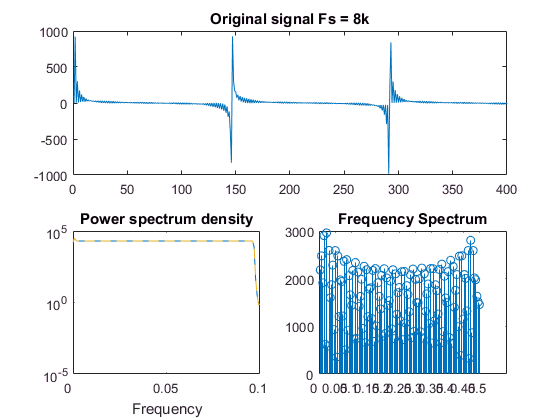

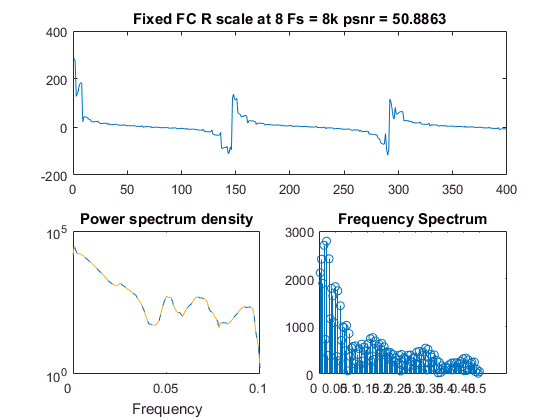

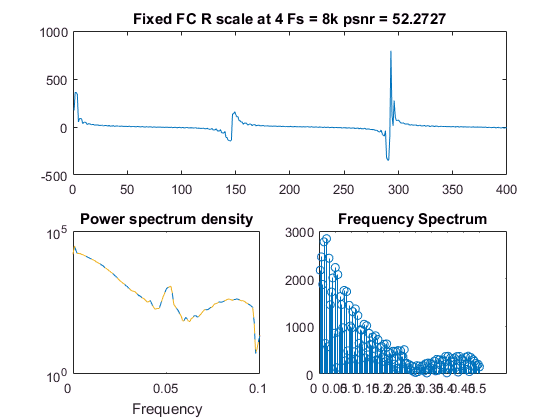

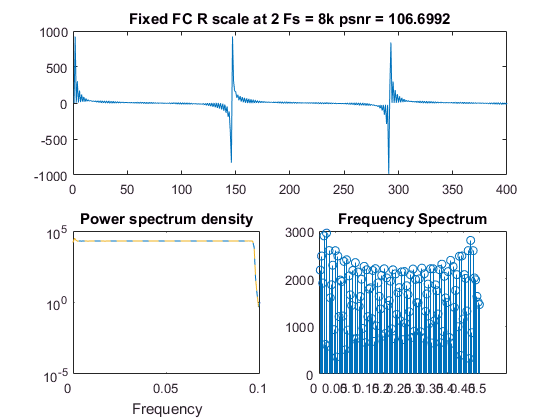

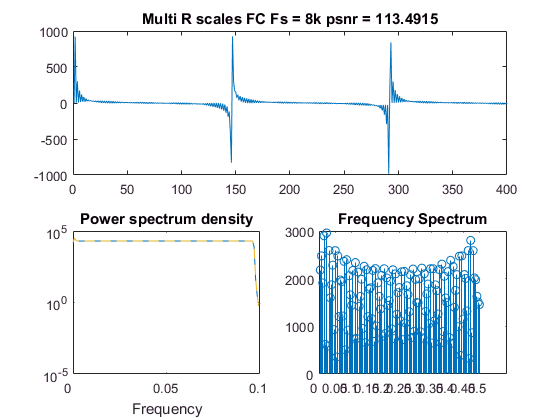

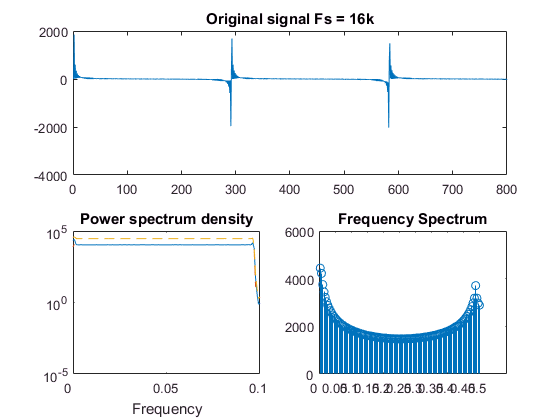

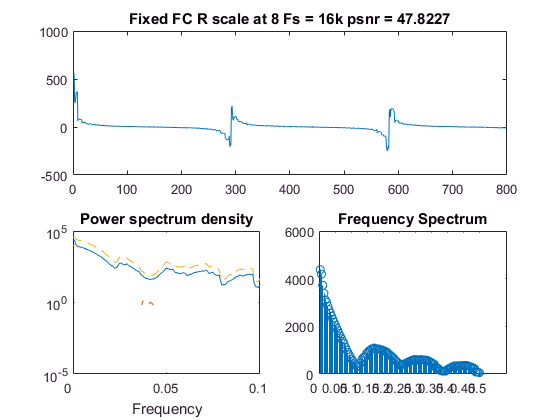

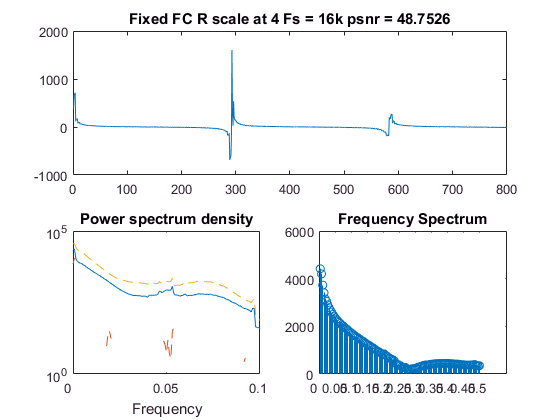

warning off 
%% parameters
RBS = [8 4 2];
Fs_inout = [1 1]; % Fs in/out ratio

%% read speech-paths
sigDir = 'F:\IFEFSR\SamplesSpeech\synth';
codeDir = 'F:\IFEFSR\SamplesSpeech\code';
filePathsLoc = 'F:\IFEFSR\SamplesSpeech\synth_ids8.txt';
fid = fopen(filePathsLoc,'r');
allFilePaths = textscan(fid, '%s','Delimiter','\n');
allFilePaths = allFilePaths{1};
fclose(fid);

%% for 
for fsIdx = 1:2
    FsShort = 8*fsIdx;
    for idx = 1:1
        %% Read original sig for baseline
        inSigPath = normpath([sigDir '\' num2str(FsShort) ...
            '\' allFilePaths{idx}]);
        sig = rawread(inSigPath);
        
        % plot original sig
        caption = ['Original signal Fs = ' num2str(FsShort) 'k'];
        plotSigVsFreqRes( sig, caption, Fs_inout(2) );
        
        %% read code from dataset
        % no need to use matlab
        F = cell(size(RBS));
        for rbsIdx = 1:length(RBS)
            inCodePath = normpath([ codeDir '\SUBSYNTH' num2str(FsShort) ...
                '_FIXED_PARTITION_RBS' num2str(RBS(rbsIdx)) '_LC099'  ...
                '\' regexprep(allFilePaths{idx}, '.raw', '.mat')]);
            dat = load(inCodePath);
            F(rbsIdx) = {dat.f};
            recSig = decompressAudioFC(dat.f, Fs_inout(1), Fs_inout(2), 15);
            
            % plot the signal
            caption = ['Fixed FC R scale at ' num2str(RBS(rbsIdx)) ' Fs = ' num2str(FsShort)  ...
                'k psnr = ' num2str(PSNR(sig, recSig))];
            plotSigVsFreqRes( recSig, caption, Fs_inout(2) );
        end
        
        %% Multi R coding section
        recSig = MultiScaleAFCDecoder(F, Fs_inout(1), Fs_inout(2), 15);
        caption = ['Multi R scales FC' ' Fs = ' num2str(FsShort)  ... 
            'k psnr = ' num2str(PSNR(sig, recSig))];
        plotSigVsFreqRes( recSig, caption, Fs_inout(2) );
        
    end
end

% parameters
RBS = [8 4 2];
lambda = 0;
Fs_inout = [1 1]; % Fs in/out ratio

% read speech-paths
workingdir = 'F:\IFEFSR\SamplesSpeech';
filePathsLoc = [workingdir '\ids8.txt'];
fid = fopen(filePathsLoc,'r');
allFilePaths = textscan(fid, '%s','Delimiter','\n');
allFilePaths = allFilePaths{1};
fclose(fid);

for fsIdx = 1:2
    FsShort = 8*fsIdx;
    for idx = 1:1
        
        %% read original sig for baseline
        inSpeechPath = normpath([workingdir '\speech\' num2str(FsShort) ...
            '\' allFilePaths{idx}]);
        sig = rawread(inSpeechPath);
        
        %% read code from dataset
        % no need to use matlab
        F = cell(size(RBS));
        for rbsIdx = 1:length(RBS)
            
            inCodePath = normpath([ 'F:\IFEFSR\AudioFC\FC\QR\SUBAN4' num2str(FsShort) ...
                '_FIXED_PARTITION_RBS' num2str(RBS(rbsIdx))  ...
                '\' regexprep(allFilePaths{idx}, '.raw', '.mat')]);
            dat = load(inCodePath);
            F(rbsIdx) = {dat.f};
        end
        
        %% Multi R coding section
        recSig = MultiScaleAFCDecoder(F, Fs_inout(1), Fs_inout(2), 15);
        caption = ['Multi R scales FC' ' psnr = ' num2str(PSNR(sig, recSig))];
        plotSigVsFreqRes( recSig, caption, Fs_inout(2) );
        
    end
end